Modeling a glacier's response to climatic change as described in Nye (1960) with Forward Euler discretization

Ella Stewart & Luke Dorrian 

**Introduction**

Glaciers and major ice sheets are sensitive indicators of climate, as they exhibit complex relationships with forcing from the atmosphere and ocean. Variations in precipitation (snowfall), surface melt (precipitation/hydrology), and calving can result from these climate forces, and glaciers can respond by advancing (growing) or retreating (shortening) accordingly. The thickness of the ice sheet can also change. The purpose of this project is to implement a version of the model spelled out in Nye (1960) to investigate thickness changes in response to seasonal and climatic variability in net accumulation.

The model applied in this project is a 1-D flowline model, which breaks a 2-D ice sheet into columns, and changes in flow are depth-integrated. A more complex flowline model would be a depth-dependent model, where the vertical columns are parceled into stacks of squares. Further complexity is added in 2-D models and 3-D models. 

**Equations**

The model spelled out in Nye (1960) describes ice as a one-dimensional flow system, where the ice gains masss via snowfall. Net accumulation can prescribe that the system loses mass if evaporation or other processes outweigh snowfall precipitation. The variation in the accumulation term is where climatic changes can be introduced to the model for ice flow. The driving force of gravity allows ice flux to occur downslope. 

The model gives a differential equation that describes changes in ice flow and thickness when exposed to some accumulation rate, a:


$$\[ \frac{\partial{q}} {\partial{x}} + \frac{\partial{h}} {\partial{t}} = a \]
$$


where h is ice thickness and q is ice flux. 

We take this equation to be similar to an advection equation which can be represented as:

 
$$\[ \frac{\partial h}{\partial t} + \frac{\partial h}{\partial x}(uh) = a\]$$


Ice velocity, u, is defined as:


$$\[ u = \frac{\rho g h sin(\alpha)} {A}^{m} \]$$


where $\rho$ is ice density ($$ \rho_i = 917 \frac{kg}{m^3} $$), g is gravitational acceleration (g = 9.81 $$ \frac{m}{s^2} $$), A is the basal roughness parameter (Dr. Robel gave us the parameter A  = $ $7*10^{6}$$ $$ m^{-1/3} s^{1/3}$$ ), and m is 3 (The paper uses m = 2, but  this value was suggested by Dr. Robel). In our implementation, we remove the sin function from this equation based on the assumption that sin($$ \alpha $ $) at small $$ \alpha $ $ will evaluate to $$ \alpha $ $. 

Surface slope, $$\alpha$$, is defined in the paper as:


$$\[ \alpha = \beta - \frac{\partial{h}}{\partial{x}} \]$$


where $$\beta$
$ is the bed slope. As per Dr. Robel's suggestion, we used a $$\beta$
$ = $$1.5*10^{-3}$$. We make the assumption that spatial changes in thickness are negligible compared to bed slope, so we simplify this expression to $$\alpha$$ = $$\beta$
$. The conclusions mention issues we had with this assumption. 

The paper suggests that the model can introduce seasonal or climatic variability in the a term for accumulation with the following equation:


$$\[ a(x,t) = a_0(x) + a_1(x,t) \]$$


where $ $a_1$
$ may encompass seasonal variability in accumulation or a longer-term climatic variability. In our simulations, we evaluate two methods for introducing climatic variability, one where *a* varies with a function of sine and another where *a* swiftly decreases from a positive regime to a negative regime within a 100-year period in the middle of the simulation. 

**Numerical methods**

We employ an upwind, Forward Euler scheme with a small $$ \Delta t $$ and small $$ \Delta x $$ to avoid instability. Since this model is essentially a nonlinear diffusion equation, stability is difficult to ensure, but we found a $$ \Delta t $$ of half a day (in terms of seconds), and a $$ \Delta x $$ of 100 meters to be stable in our simulations.

The Forward Euler discretization gives the following marching equation:


$$\[ h_i^{k+1} = h_i^{k} +  \frac{\Delta t}{\Delta x} (h_i^{k} u_i^{k} + h_{i-1}^{k} u_{i-1}^{k}) + a\]
$$


where i represents a space index and k represents a time index.

For boundary conditions, we set the initial glacier thickness at the ice divide and the thickness at the end of the glacier. We also have a Neumann boundary condition, where $$ \frac{\partial h}{\partial x} = 0 $$ at the end of the glacier. We found how this would be implemented in the marching equation with the following:


$$\[ \frac{\partial h}{\partial t} = -\frac{\partial h}{\partial x}(uh) + a \]
$$



$$\[ \frac{\partial h}{\partial x} = \frac{h_i^{k} - h_{i-1}^{k}}{\Delta x} = 0\] $$
 


$$\[  \frac{h_i^{k+1} - h_{i}^{k}}{\Delta t} =  -\frac{h_i^{k} - h_{i-1}^{k}}{\Delta x} + a \]$$



$$\[h_i ^{k+1} = h_i^{k} + a$$


This is expressed in our code where the variable dqdtdx is set to 0 at position x(end). 

For the Neumann boundary condition at the front of the glacier, we assume that 


$$\[h_1^{k+1} = h_1^{k} + \frac{\Delta t}{\Delta x}h_1^{k}u_1^k +a$$


so that changes in ice velocity would apply at this first boundary and flux would be applied. We initially believed that the front and end boundary should have the same Neumann condition, and in that case, the profile evolution was very different. This is discussed further in the results section. 

**Results**

For the following simulations:

- Initial inland thickness is 3000 meters and decreases with a slope of $$3*10^{-3}$ over the length of the glacier.  

- Glacier length is 50,000 meters.

- Bed slope is $$ -1.5*10^{-3}$.

- Initial ice velocity is 20 m/yr.

- $$ \Delta t $$ is half a day (in seconds).

- $$ \Delta x$$ is 100 meters.

- We run the simulation for 4000 years. 

In the following simulations, we vary accumulation. The final plot will show how accumulation varies in time for each of these. 

1) The first simulation we present is with constant, positive accumulation over the duration of the simulation. 

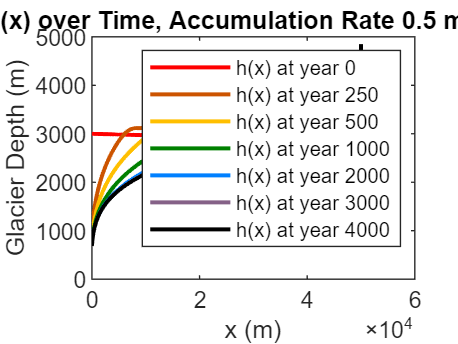

% simulation 1 setup 
accum_i = 0.5;
beta = -1.5*(10^-3);
tf = 4000;
variesSine = false;
variesClimate = false; 

% run model 
[all_x, all_h, accum_1] = nye_model(accum_i, tf, beta, variesSine, variesClimate);
% make plot 
orange = [.8, .33, 0]; yellow = [1 .75 0]; green = [0 .5 0]; blue = [0 .5 1]; violet = [.52 .38 .53]; % figure colors 
figure;
plot(all_x, all_h(1,:), 'r', 'LineWidth', 1.5);
hold on;
plot(all_x, all_h(251,:), 'color', orange, 'LineWidth', 1.5);
plot(all_x, all_h(501,:), 'color', yellow, 'LineWidth', 1.5);
plot(all_x, all_h(1001,:), 'color', green, 'LineWidth', 1.5);
plot(all_x, all_h(2001,:), 'color', blue, 'LineWidth', 1.5);
plot(all_x, all_h(3001,:), 'color', violet, 'LineWidth', 1.5);
plot(all_x, all_h(4001,:),  'k', 'LineWidth', 1.5);
legend('h(x) at year 0', 'h(x) at year 250', 'h(x) at year 500', 'h(x) at year 1000', 'h(x) at year 2000', ...
    'h(x) at year 3000', 'h(x) at year 4000');
title(['H(x) over Time, Accumulation Rate ' num2str(accum_i) ' m/year']);
xlabel('x (m)');
ylabel('Glacier Depth (m)');

2) The second simulation we present is with constant, negative accumulation over the duration of the simulation. 

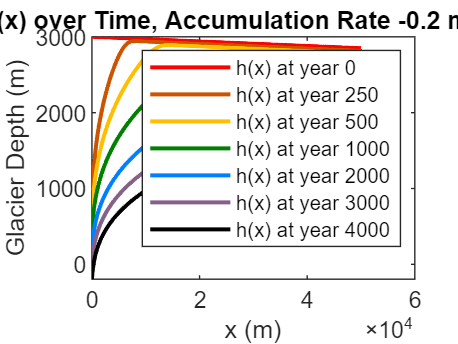

% simulation 2 setup 
accum_i = -0.2;
beta = -1.5*(10^-3);
tf = 4000;
variesSine = false;
variesClimate = false; 

% run model 
[all_x, all_h, accum_2] = nye_model(accum_i, tf, beta, variesSine, variesClimate);

% make plot 
orange = [.8, .33, 0]; yellow = [1 .75 0]; green = [0 .5 0]; blue = [0 .5 1]; violet = [.52 .38 .53]; % figure colors 
figure;
plot(all_x, all_h(1,:), 'r', 'LineWidth', 1.5);
hold on;
plot(all_x, all_h(251,:), 'color', orange, 'LineWidth', 1.5);
plot(all_x, all_h(501,:), 'color', yellow, 'LineWidth', 1.5);
plot(all_x, all_h(1001,:), 'color', green, 'LineWidth', 1.5);
plot(all_x, all_h(2001,:), 'color', blue, 'LineWidth', 1.5);
plot(all_x, all_h(3001,:), 'color', violet, 'LineWidth', 1.5);
plot(all_x, all_h(4001,:),  'k', 'LineWidth', 1.5);
legend('h(x) at year 0', 'h(x) at year 250', 'h(x) at year 500', 'h(x) at year 1000', 'h(x) at year 2000', ...
    'h(x) at year 3000', 'h(x) at year 4000');
title(['H(x) over Time, Accumulation Rate ' num2str(accum_i) ' m/year']);
xlabel('x (m)');
ylabel('Glacier Depth (m)');

3) The third simulation includes is accumulation that varies in time with this function of sine: 


$$$ sin\frac{(t-250\pi)}{500} + 0.03  $ $$


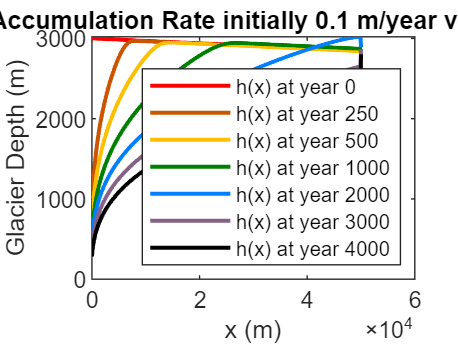

% simulation 3 setup 
accum_i = 0.1;
beta = -1.5*(10^-3);
u_i = 20; 
tf = 4000;
variesSine = true;
variesClimate = false; 

% run model 
[all_x, all_h, accum_3] = nye_model(accum_i, tf, beta, variesSine, variesClimate);

% make plot 
orange = [.8, .33, 0]; yellow = [1 .75 0]; green = [0 .5 0]; blue = [0 .5 1]; violet = [.52 .38 .53]; % figure colors 
figure;
plot(all_x, all_h(1,:), 'r', 'LineWidth', 1.5);
hold on;
plot(all_x, all_h(251,:), 'color', orange, 'LineWidth', 1.5);
plot(all_x, all_h(501,:), 'color', yellow, 'LineWidth', 1.5);
plot(all_x, all_h(1001,:), 'color', green, 'LineWidth', 1.5);
plot(all_x, all_h(2001,:), 'color', blue, 'LineWidth', 1.5);
plot(all_x, all_h(3001,:), 'color', violet, 'LineWidth', 1.5);
plot(all_x, all_h(4001,:),  'k', 'LineWidth', 1.5);
legend('h(x) at year 0', 'h(x) at year 250', 'h(x) at year 500', 'h(x) at year 1000', 'h(x) at year 2000', ...
    'h(x) at year 3000', 'h(x) at year 4000', 'Location', 'southeast');
title(['H(x) over Time, Accumulation Rate initially ' num2str(accum_i) ' m/year varies as a fxn of sine']);
xlabel('x (m)');
ylabel('Glacier Depth (m)');

4) The fourth simulation includes accumulation that represents a logarithmic downshift in net accumulation at 2000 years. There is noise added to accumulation both before and after this climatic shift. 

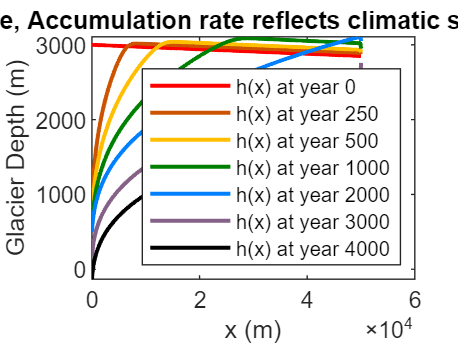

% simulation 4 setup 
accum_i = 0.1;
beta = -1.5*(10^-3);
tf = 4000;
variesSine = false;
variesClimate = true; 

% run model 
[all_x, all_h, accum_4] = nye_model(accum_i, tf, beta, variesSine, variesClimate);

 % make plot 
orange = [.8, .33, 0]; yellow = [1 .75 0]; green = [0 .5 0]; blue = [0 .5 1]; violet = [.52 .38 .53]; % figure colors 
figure;
plot(all_x, all_h(1,:), 'r', 'LineWidth', 1.5);
hold on;
plot(all_x, all_h(251,:), 'color', orange, 'LineWidth', 1.5);
plot(all_x, all_h(501,:), 'color', yellow, 'LineWidth', 1.5);
plot(all_x, all_h(1001,:), 'color', green, 'LineWidth', 1.5);
plot(all_x, all_h(2001,:), 'color', blue, 'LineWidth', 1.5);
plot(all_x, all_h(3001,:), 'color', violet, 'LineWidth', 1.5);
plot(all_x, all_h(4001,:),  'k', 'LineWidth', 1.5);
legend('h(x) at year 0', 'h(x) at year 250', 'h(x) at year 500', 'h(x) at year 1000', 'h(x) at year 2000', ...
    'h(x) at year 3000', 'h(x) at year 4000', 'Location', 'southeast');
title(['H(x) over Time, Accumulation rate reflects climatic shift @ 2000 years']);
xlabel('x (m)');
ylabel('Glacier Depth (m)');

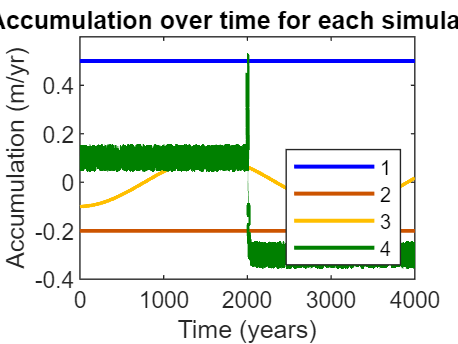

% accumulation plot 
all_t = 0:tf;
figure();
plot(all_t, accum_1, 'blue', 'LineWidth', 1.5); 
hold on;
plot(all_t, accum_2, 'color', orange, 'LineWidth', 1.5); 
plot(all_t, accum_3, 'color', yellow, 'LineWidth', 1.5); 
plot(all_t, accum_4, 'color', green, 'LineWidth', 1.5); 
title('Accumulation over time for each simulation');
xlabel('Time (years)'); ylabel('Accumulation (m/yr)');
legend('1', '2', '3', '4', 'Location', 'southeast');

**Results**

We found that the time step of half a day (43200 seconds) was stable. Greater time steps, such as by year, introduced instability in the model. The 100 meter grid spacing also proved to be a stable choice for this discretization. Larger grid spacing introduced instability. The code takes a long time to run, so we capped the final time at 4000 years, but steady states may have been more interesting to observe if the model were to run for a longer period, so long as a is constant.

Boundary conditions affect the steady state of the model. When we set dqdtdx = 0 at both the front and end of the glacier, the profiles are different from those expressed here. Instead of exhibiting a steep drop at the front which smoothes out over time, the front of the glacier evolves to a flat surface profile and the surface past this extent maintains a constant slope. Through time, the extent of the flat surface is extended along the glacier, and our simulation length doesn’t show a steady surface profile. This leads us to believe the slope might eventually become 0 everywhere on the surface. This may be the result of our parameterization of alpha. 

1) For the constant positive accumulation rate, the results show the thickness growing in time, and then decreasing again. The flux at the front of the glacier is much higher than the accumulation rate, so there is a drop in thickness at the front as the mass is fluxed forward and pushed downslope. The thickness profile smooths out with time and reaches a relatively steady profile by the 3000 year mark, although the final point is expressing some strange behavior, indicating our boundaries may not be implemented correctly. Smaller accumulation rates would likely result in different time evolutions, where the accumulation would not outweigh the thickness flux and the glacier would shorten over time, and a greater rate that would overpower flux in time would continue to grow.

2) For the constant negative accumulation rate, the thickness shrinks in time, and the same evolution of the dh/dx profile smoothness from the first simulation is true: a steady profile is found by year 3000. While the larger positive rate sees growth and then shrinking, this smaller negative rate only sees shrinking thickness in time. 

3) For the variable accumulation rate, the evolution looks similar to that of the positive one. The small changes in accumulation over such a long time likely average out to a similar forcing.

4) For the climatic change simulation, the thickness initially grows, then shrinks after the 2000 year accumulation shift. The thickness profile appears to steady/smooth out by year 2000. 

It is difficult to compare the results of our very simple and imperfect model to those in scientific literature. The finding of a steady dh/dx profile seems to be consistent with other thickness model findings, however. Mueller et al. (2016) finds the evolution of absolute thickness for a rock glacier, and while the thickness starts off with a rough profile with a sharp drop at the end, a smooth, steady profile is reached with time. 

**Conclusions**

Our model is simple and makes several assumptions that oversimplify the cryosphere dynamics. However, we encountered some issues with implementing appropriate boundary conditions and accounting for changing surface slope. Still, we can see how the evolution of glacier thickness changes with accumulation, and how a climatic shift can be internalized by the glacier and result in dramatic changes to the glacier. Our model follows the logical idea that mass would flow primarily downhill, but fails to realize the reverse motion that may occur from higher glacier heights in downstream parcels.  

There are certainly more processes in reality that regulate glacier height change as our height changes far more rapidly than glacier height change observed on Earth. Some improvements would include adding in some more realistic variability for accumulation (i.e. seasonal), incorporating 3-D geographic variability, and implementing a more realistic spatial profile of accumulation, where ice accumulates near the ice divide and loses mass further downstream in an ablation zone. 

Originally, we intended to have alpha as a function of x where alpha = beta - dh/dx. This caused immediate instability to our model. Further research found that this relationship can only apply when (dh/dx) << 1 (Nye, 1960). When the height increased with x (due to upstream positive mass flow), this immediately induced instability. In order to stabilize this model, spatial stepping would need to be quite small. To improve this model, a proper relationship between dh/dx and u should be found that does not induce instability in the model. 

**References**

Mueller, J., Vielli, A., & Gärtner-Roer, I. (2016). Rock glaciers on the run - Understanding rock glacier landform evolution and recent changes from numerical flow modeling. The Cryosphere. v. 10(6), p. 2865-2886, doi:10.5194/tc-10-2865-2016.

Nye, J. F. (1960). The response of glaciers and ice-sheets to seasonal and climatic changes. Proc. R. Soc. Land. v. 256, p. 559-584, doi:10.1098/rpa.1960.0127.

% model code:

function[all_x, all_h, accum] = nye_model(accum_i, tf, beta, variesSine, variesClimate)
%% initializations
rho = 917;            % ice density (kg/m^3)
g = 9.81;             % gravitational acceleration (m/yr^2)
m = 3;                % constant = 1/2(n + 1), so ~ 2, now 3
A = 7*10^6;           % basal roughness, need to consult Robel
beta = beta;  % bed slope

% set dx and dt
dx = 100;               % x grid spacing, meters
dy = 1;                 % time step, years
tf = tf;                % length of simulation, years
t = 0:dy:tf;            % time vector, years
s_year = 365*60*60*24*7;% seconds in a year
s_day = 24*60*60;       % seconds in a day
dt = s_day*.5;          % portion of a year

% space (x) and thickness (h)
h_i = 3000;                              % initial thickness (meters)
glacier_length = 50000;                  % glacier length (meters) ... somewhere around this
all_x = 0:dx:glacier_length;             % position vector (meters)
all_h = zeros(length(t), length(all_x)); % thickness vector (meters)
all_h(1,1) = h_i;                        % set inland thickness
all_h(1,:) = h_i - all_x.*(3*10^-3);     % rows are time, columns being h(x,t)
h_temp(1:length(all_x)) = 0;

% characterize accumulation and set initial ice velocity
accum_i = accum_i; % initial accumulation rate (meters/year)
u_i = 20;    % initial ice velocity (meters/year)

if variesSine
    accum = accum_i*sin((t-250*pi)/(500) + 0.03); % varies accumulation with a fxn of sin about accum_i
elseif variesClimate
    accum = zeros(1, length(t));
    accum_f = -0.3; % drops to -0.3 m/yr
    accum(1:2000) = accum_i; 
    deltaE = accum - accum_f;
    accum(2001:2100) = 0.5 - 0.8.*(1 - logspace(0, -5, 100)); % sharp drop over 100 years beginning after 2000 years
    accum(2101:length(t)) = accum_f;
    accum = accum + rand(1,length(t))*0.1 - 0.05; % add noise
else
    accum(1:length(t)) = accum_i; % constant accumulation for entire simulation
end

%% initialize outputs
% go through each function h(x,t), calculate a(x) then u(x)
dqdtdx(1:length(all_x)) = 0;
u_array = zeros(length(t),length(all_x));
a_array = u_array; % alpha -> surface slope

%% step through model
for k = 1:(length(t) - 1)
    h_temp = all_h(k,:);

    for n = 1:(365*2) % two years total, iterated by day, in terms of seconds
        h_copy = h_temp; % current thickness vector

        % redefine surface slope
        h_diff = diff(h_copy);
        a_apply(1:length(all_x)) = beta;

        % find ice velocity
        u_apply = (((rho*g/A)^m).*(h_copy.^m).*abs(a_apply.^m)); %assumes sin(a) == a, this change made it more stable

        % find dt*dq/dx
        dqdtdx(1) = (dt/dx)*h_copy(1)*u_apply(1); % front boundary condition
        for i = 2:length(all_x)-1
            dqdtdx(i) = (dt/dx)*(h_copy(i)*u_apply(i) - h_copy(i-1)*u_apply(i-1));
        end
        dqdtdx(end) = 0; % end boundary condition
        h_temp = h_copy - dqdtdx + accum(k)/(365*2);

    end

    % update arrays
    u_array(k,:) = u_apply*(365*s_day)*2;
    a_array(k,:) = a_apply;
    all_h(k+1,:) = h_temp;

end
end
